## CÓDIGO AÑADIDO:

table = []
for i=1:readDigits
    img = imgs(:, :, i); % 1
    img = imresize(img, [40, 40]);
    
    % Concavities 
    img = im2bw(img, graythresh(img));
    imgWithoutHoles = imfill(img, 'holes');
    
    ch = bwconvhull(imgWithoutHoles, 'objects');
    
    concavities = ch-imgWithoutHoles;
    
    [eti num] = bwlabel(concavities,4);
    
    Dades = regionprops(eti,'all');
    
    N = 3;
    T = struct2table(Dades);
    toDelete = T.Area < 4;
    T(toDelete,:) = [];
    sortedT = sortrows(T, 'Centroid', "descend");
    Dades = table2struct(sortedT);
    Dades = Dades(1:min(size(Dades, 1), N));
    
    centroidsX = zeros(1, N);
    centroidsY = zeros(1, N);
    area = zeros(1, N);
    majorAxisLength = zeros(1, N);
    minorAxisLength = zeros(1, N);
    
    for i=1:size(Dades, 1)
        dada = Dades(i);
        centroidsX(1, i) = dada.Centroid(1);
        centroidsY(1, i) = dada.Centroid(2);
        area(1, i) = dada.Area;
        majorAxisLength(1, i) = dada.MajorAxisLength;
        minorAxisLength(1, i) = dada.MinorAxisLength;
    end
    features = [centroidsX centroidsY area majorAxisLength minorAxisLength];
    
    % Holes  
    imgWithoutHoles = imfill(img, 'holes');
    
    holes = imgWithoutHoles-img;

    [eti, num] = bwlabel(holes,4);
    
    Dades = regionprops(eti,'all');
        
    N = 2;
    if size(Dades, 1) > 1
        T = struct2table(Dades);
        toDelete = T.Area < 4;
        T(toDelete,:) = [];
        sortedT = sortrows(T, 'Centroid', "descend");
        Dades = table2struct(sortedT);
        Dades = Dades(1:min(size(Dades, 1), N));
    end
    
    centroidsX = zeros(1, N);
    centroidsY = zeros(1, N);
    area = zeros(1, N);
    majorAxisLength = zeros(1, N);
    minorAxisLength = zeros(1, N);
    
    for i=1:size(Dades, 1)
        dada = Dades(i);
        centroidsX(1, i) = dada.Centroid(1);
        centroidsY(1, i) = dada.Centroid(2);
        area(1, i) = dada.Area;
        majorAxisLength(1, i) = dada.MajorAxisLength;
        minorAxisLength(1, i) = dada.MinorAxisLength;
    end
    features = [features centroidsX centroidsY area majorAxisLength minorAxisLength];

    table = [table ; array2table(features)];
end
table.Labels = labels


## CÓDIGO NO AÑADIDO:

% Data parameters
imgFile = "train-images-idx3-ubyte";
labelFile = "train-labels-idx1-ubyte";
readDigits = 100;
offset = 0;

[imgs labels] = readMNIST(imgFile, labelFile, readDigits, offset);


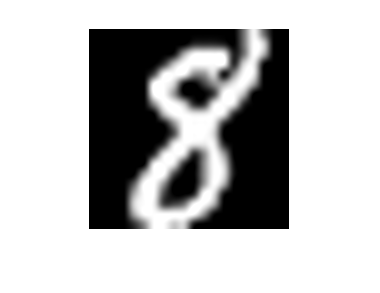


% holes
img = imgs(:, :, 42);
img = imresize(img, [200, 200]);

figure, imshow(img)

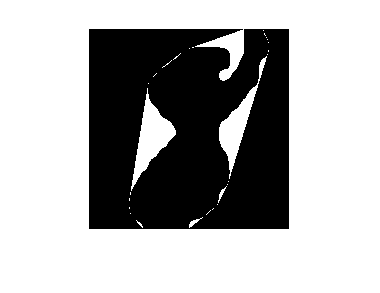


img = im2bw(img, graythresh(img));
imgWithoutHoles = imfill(img, 'holes');

ch = bwconvhull(imgWithoutHoles, 'objects');

concavities = ch-imgWithoutHoles;

figure, imshow(concavities)

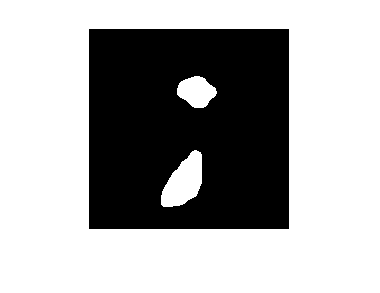


imgWithoutHoles = imfill(img, 'holes');
holes = imgWithoutHoles-img;

figure, imshow(holes)

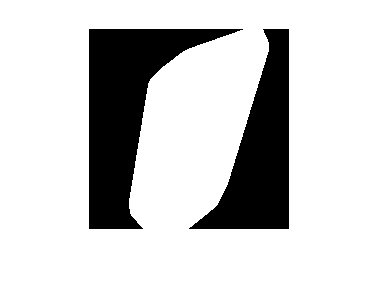


ch = bwconvhull(img, 'objects');

figure, imshow(ch)

% corners
img = imgs(:, :, 13);
C = corner(img, 'Harris', 100, 'QualityLevel', 0.3); imshow(img) 
C

C =      6    18
    20    14
    11     5
     8    10
    14     8
    14    15


size(C, 1)

ans = 6

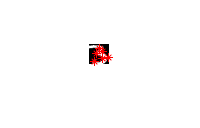

hold on 
plot(C(:,1),C(:,2),'r*');


extractHOGFeatures(img,'CellSize',[4 4])

ans = 1×576 single row vector
         0         0         0    0.0297    0.4002    0.4002    0.0141         0         0         0         0         0         0    0.4002    0.2310         0         0         0         0         0         0    0.1989    0.4002    0.2788    0.0084         0         0         0         0         0         0    0.4002    0.1582    0.0456    0.0142         0    0.0058         0         0         0    0.2989    0.2830         0         0    0.0058    0.0304         0         0         0         0


features = zeros(readDigits, 576)

features =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0  

for i=1:readDigits
    img = imgs(:, :, i);
    features(i, :) = extractHOGFeatures(img,'CellSize',[4 4]);
end
table2 = array2table(features)

table2 = 100×576 table
    features1     features2    features3    features4    features5     features6    features7    features8    features9     features10    features11    features12    features13    features14    features15    features16    features17    features18    features19    features20    features21    features22    features23    features24    features25    features26    features27    features28    features29    features30    features31    features32

table2.labels = labels;


% model calculation
numOfHoles = zeros(readDigits, 1);
holesTotalArea = zeros(readDigits, 1);
totalArea = zeros(readDigits, 1);
numOfCorners = zeros(readDigits, 1);
for i=1:readDigits
    img = imgs(:, :, i);
    imgRes = imresize(img, [40, 40]);
    
    img = imbinarize(img, graythresh(img));
    
    totalArea(i, 1) = bwarea(img);
    
    imgWithoutHoles = imfill(img, 'holes');
    
    holes = imgWithoutHoles-img;

    [eti, num] = bwlabel(holes,4);
    
    Dades = regionprops(eti,'all');
    
    [n, m] = size(Dades);
    numOfHoles(i, 1) = n;
    
    holesTotalArea(i, 1) = sum([Dades(:).Area]);
    
    C = corner(imgRes, 'Harris', 100, 'QualityLevel', 0.5);
    numOfCorners(i, 1) =  size(C, 1);
    
    
end
table.numOfHoles = numOfHoles;
table.holesTotalArea = holesTotalArea;
table.totalArea = totalArea;
table.numOfCorners = numOfCorners

table = struct with fields:
        numOfHoles: [100×1 double]
    holesTotalArea: [100×1 double]
         totalArea: [100×1 double]
      numOfCorners: [100×1 double]


table.labels = labels;
table

table = struct with fields:
        numOfHoles: [100×1 double]
    holesTotalArea: [100×1 double]
         totalArea: [100×1 double]
      numOfCorners: [100×1 double]
            labels: [100×1 double]


table = []
for i=1:readDigits
    img = imgs(:, :, i); % 1
    img = imresize(img, [40, 40]);
    ch = bwconvhull(img, 'objects');
    [eti num] = bwlabel(ch,4);
    dada = regionprops(eti,'all');
    centroidsX = dada.Centroid(1);
    centroidsY = dada.Centroid(2);
    area = dada.Area;
    majorAxisLength = dada.MajorAxisLength;
    minorAxisLength = dada.MinorAxisLength;
    features = [centroidsX centroidsY area majorAxisLength minorAxisLength];
    table = [table ; array2table(features)];
end
table.Labels = labels


load fisheriris;
species

species = 150×1 cell array
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
